# Reference

Wikipedia contributors. (2022, March 1). Gaussian beam. In *Wikipedia, The Free Encyclopedia*. Retrieved 19:56, March 1, 2022, from [https://en.wikipedia.org/w/index.php?title=Gaussian_beam&oldid=1074672745](https://en.wikipedia.org/w/index.php?title=Gaussian_beam&oldid=1074672745)

# Simple Gaussian beam

Gaussian beam electric field in phaser notation


$$\mathbf{E}(r,z) = E_0\hat{\mathbf{x}}\frac{w_0}{w(z)}
\exp\left(\frac{-r^2}{w(z)^2}\right)
\exp\left(-i\left(kz+k\frac{r^2}{2R(z)}-\varphi(z)\right)\right)$$


where

$k = 2\pi n/\lambda$, $w(z) = w_0\sqrt{1+\left(\frac{z}{z_R}\right)^2}$, $z_R = \frac{\pi w_0^2 n}{\lambda}$, $R(z) = z\left[1+\left(\frac{z_R}{z}\right)^2\right]$, $\varphi(z) =  \arctan\left(\frac{z}{z_R}\right)$

Actual field is the real part of the phaser and oscillating at a frequency of $\omega$.

Beam peak intensity


$$I_0 = \frac{|E_0|^2}{2Z_0}=\frac{1}{2}\sqrt{\frac{\epsilon_0}{\mu_0}}|E_0|^2 = \frac{2P_0}{\pi w_0^2}$$


where $P_0$ is the power of single beam, $w_0$ is the beam size at the waist.

Therefore, from the beam power, one can calculate the peak electric field amplitude


$$E_0=\frac{2}{w_0}\sqrt{\frac{P_0}{\pi c\epsilon_0}}$$


The amplitude factor


$$\frac{1}{\sqrt{1+\left(\frac{\lambda z}{\pi w_0^2}\right)^2}}
\exp\left(-\frac{r^2}{w_0^2+(\lambda^2 z^2)/(\pi^2 w_0^2)}\right)$$


And the phase factor


$$\exp\left(-i\left(kz+k\frac{r^2}{2\left(
z+(\pi^2w_0^4)/(\lambda^2z)\right)}-
\arctan\left(\frac{\lambda z}{\pi w_0^2}\right)
\right)\right)$$


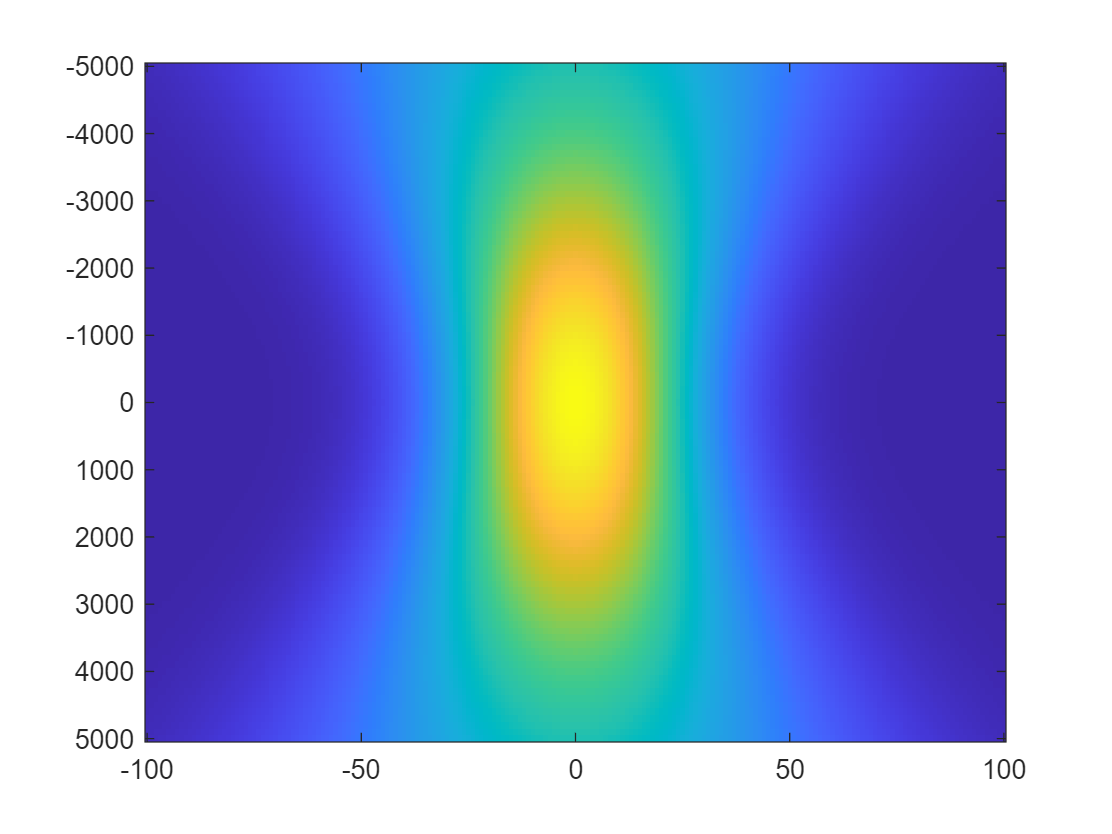

% Power is in mW, all length scale are in um
Beam.Power = 300;
Beam.Waist = 30;
Beam.Wave = 0.935;
RRange = -100:100;
ZRange = -5000:100:5000;

[X,Z] = meshgrid(RRange,ZRange);
E = reshape(gaussianSingle(Beam.Power,Beam.Waist,Beam.Wave, ...
    X(:),0,Z(:)),length(ZRange),length(RRange));
imagesc(RRange,ZRange,abs(E))

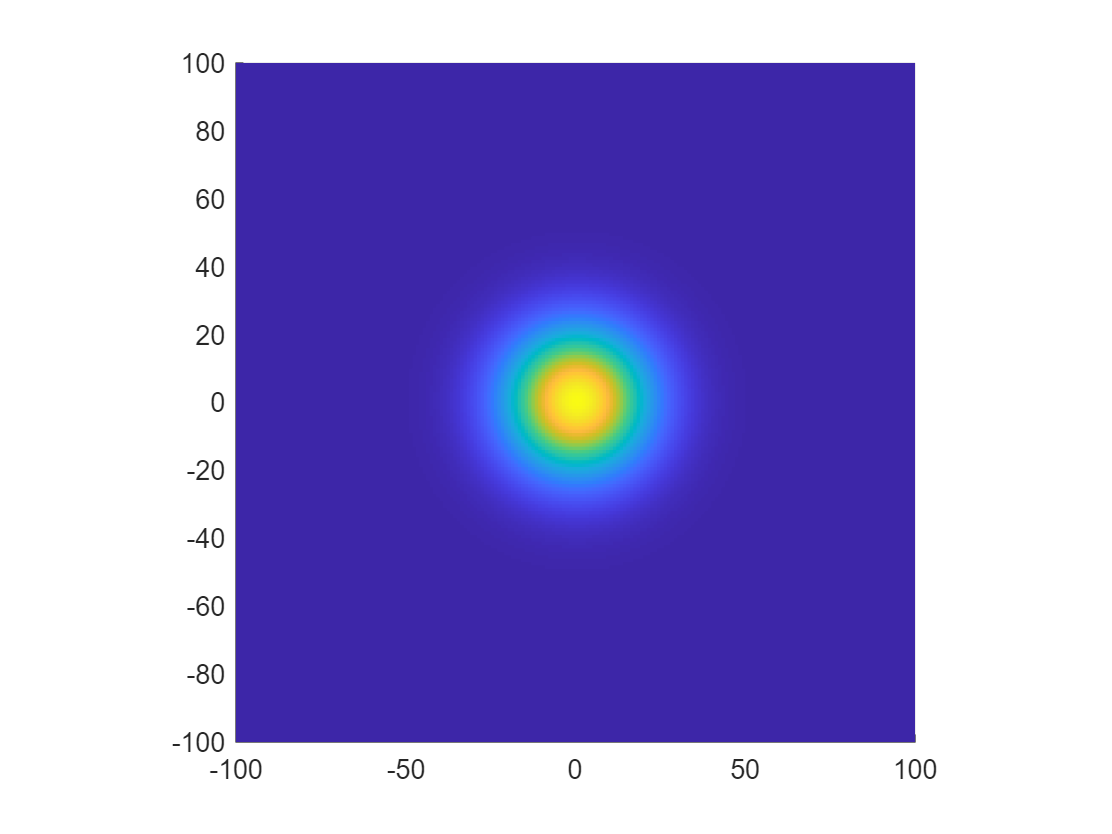

[Y,X] = meshgrid(RRange,RRange);
E = reshape(gaussianSingle(Beam.Power,Beam.Waist,Beam.Wave, ...
    X(:),Y(:),0),length(RRange),length(RRange));
surf(RRange,RRange,abs(E).^2,'EdgeColor','none')
daspect([1 1 1])
view(2)

#### Elliptical Gaussian beam


$$E_0=2\sqrt{\frac{P_0}{\pi c\epsilon_0w_xw_y}}$$


The amplitude factor


$$\frac{1}{\sqrt{1+\left(\frac{\lambda z}{\pi w_xw_y}\right)^2}}
\exp\left(-\frac{x^2}{w_x^2+(\lambda^2 z^2)/(\pi^2 w_x^2)}
-\frac{y^2}{w_y^2+(\lambda^2z^2)/(\pi^2w_y^2)}\right)$$


And the phase factor


$$\exp\left(-i\left(kz+k
\frac{x^2}{2\left(
z+(\pi^2w_x^4)/(\lambda^2z)\right)}
+k\frac{y^2}{2\left(
z+(\pi^2w_y^4)/(\lambda^2z)\right)}
-\arctan\left(\frac{\lambda z}{\pi w_xw_y}\right)
\right)\right)$$


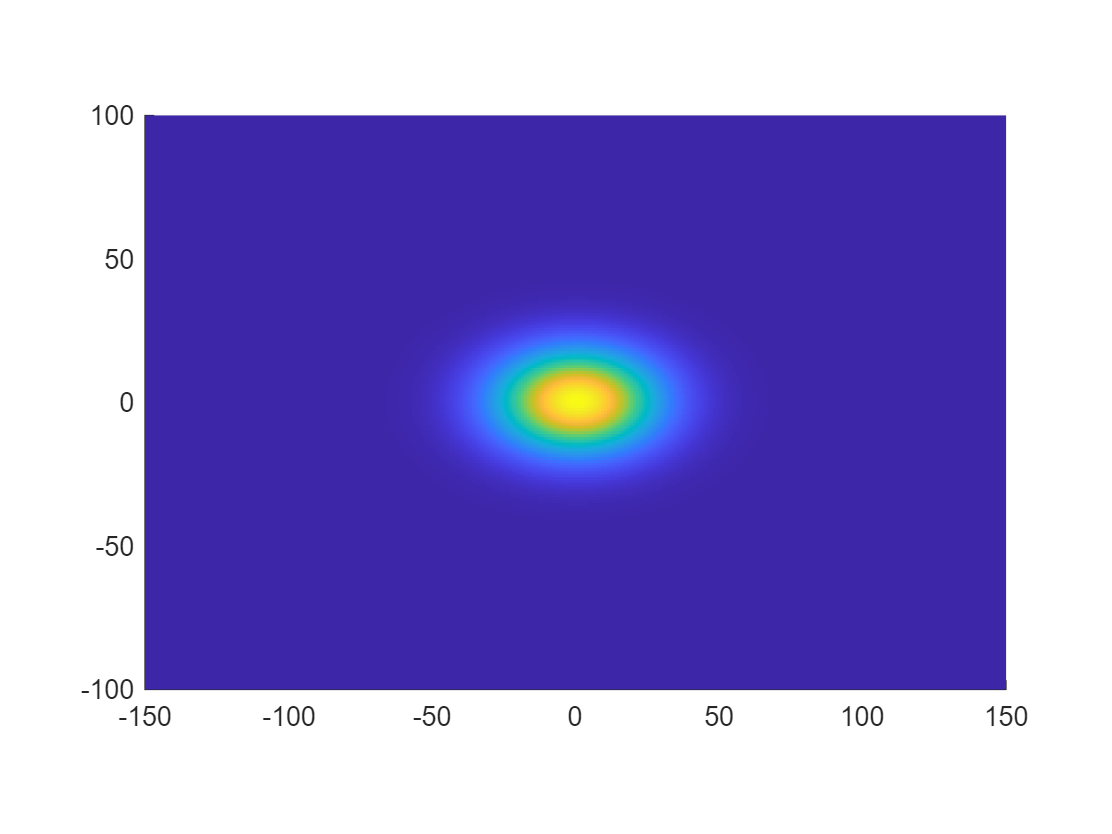

Beam.Power = 300;
Beam.Waist = [25,40];
Beam.Wave = 0.935;
XRange = -100:100;
YRange = -150:150;

[Y,X] = meshgrid(YRange,XRange);
E = reshape(gaussianSingle(Beam.Power,Beam.Waist,Beam.Wave, ...
    X(:),Y(:),0),length(XRange),length(YRange));
surf(YRange,XRange,abs(E).^2,'EdgeColor','none')
xlim([YRange(1),YRange(end)])
ylim([XRange(1),XRange(end)])
daspect([1 1 1])
view(2)

#### Frame transformation for rotation

For a set of orthognormal basis vector $\{\hat{x}, \hat{y}, \hat{z}\}$, rotating along z-axis by angle $\theta$ results in a new set of basis vectors$\{\hat{x}\prime,\hat{y}\prime,\hat{z}\prime\}$


$$\left(\begin{array}{c}
\hat{x}\prime \\
\hat{y}\prime \\
\hat{z}\prime
\end{array}\right)=\left(\begin{array}{c c c}
\cos\theta & \sin\theta & 0 \\
-\sin\theta & \cos\theta & 0 \\
0 & 0 & 1 
\end{array}\right)\left(\begin{array}{c}
\hat{x} \\
\hat{y} \\
\hat{z}
\end{array}\right)$$


Therefore, for a rotation around z-axis by angle $\theta$ followed by another rotation around y-axis by angle $\varphi$, the basis will transform as


$$\left(\begin{array}{c}
\hat{x}" \\
\hat{y}" \\
\hat{z}"
\end{array}\right)=\left(\begin{array}{c c c}
\cos\theta\cos\varphi & \sin\theta\cos\varphi & -\sin\varphi \\
-\sin\theta & \cos\theta & 0 \\
\cos\theta\sin\varphi & \sin\theta\sin\varphi & \cos\varphi
\end{array}\right)\left(\begin{array}{c}
\hat{x} \\
\hat{y} \\
\hat{z}
\end{array}\right) $$


If we define the transform matrix for basis as $T = T_y(\varphi)T_z(\theta)$, then the coordinates must transform inversely as $T^{-1} = T_z(-\theta)T_y(-\varphi)$


$$(\begin{array}{c c c}
x" & y" & z"
\end{array}) = (\begin{array}{c c c}
x & y & z
\end{array})T^{-1}$$


Therefore the coordinates transform as


$$\left(\begin{array}{c}
x" \\
y" \\
z"
\end{array}\right)=\left(\begin{array}{c c c}
\cos\theta\cos\varphi & \sin\theta\cos\varphi & -\sin\varphi \\
-\sin\theta & \cos\theta & 0 \\
\cos\theta\sin\varphi & \sin\theta\sin\varphi & \cos\varphi
\end{array}\right)\left(\begin{array}{c}
x \\
y \\
z
\end{array}\right) $$


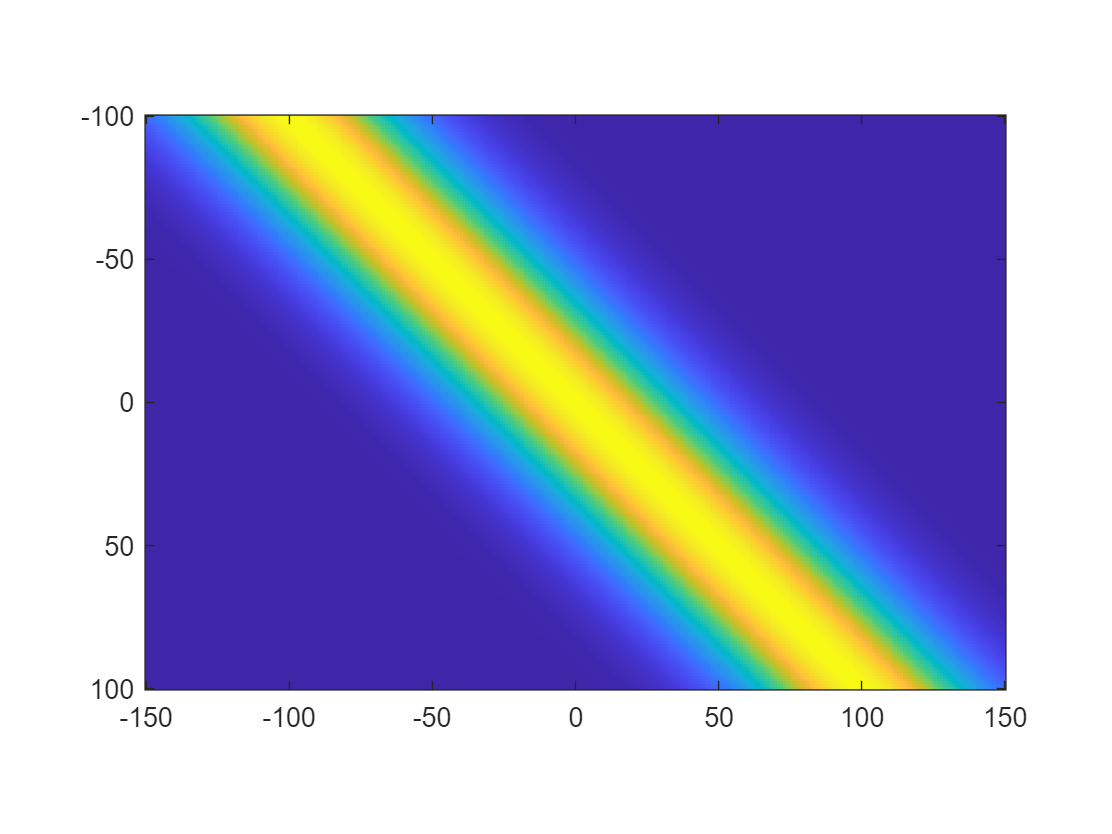

Beam.Power = 300;
Beam.Waist = [25,40];
Beam.Wave = 0.935;
Beam.Ang = [45,90];
Beam.Pol = [0,0];
XRange = -100:100;
YRange = -150:150;

[Y,X,Z] = meshgrid(YRange,XRange,0);
I = gaussianFull(Beam,[X(:),Y(:),Z(:)]);
imagesc(YRange,XRange,reshape(I,length(XRange),length(YRange)))
daspect([1 1 1])

#### Interference of beams

Total electric field is the sum of the field from each beam. The time-averaged intensity shows interference pattern.

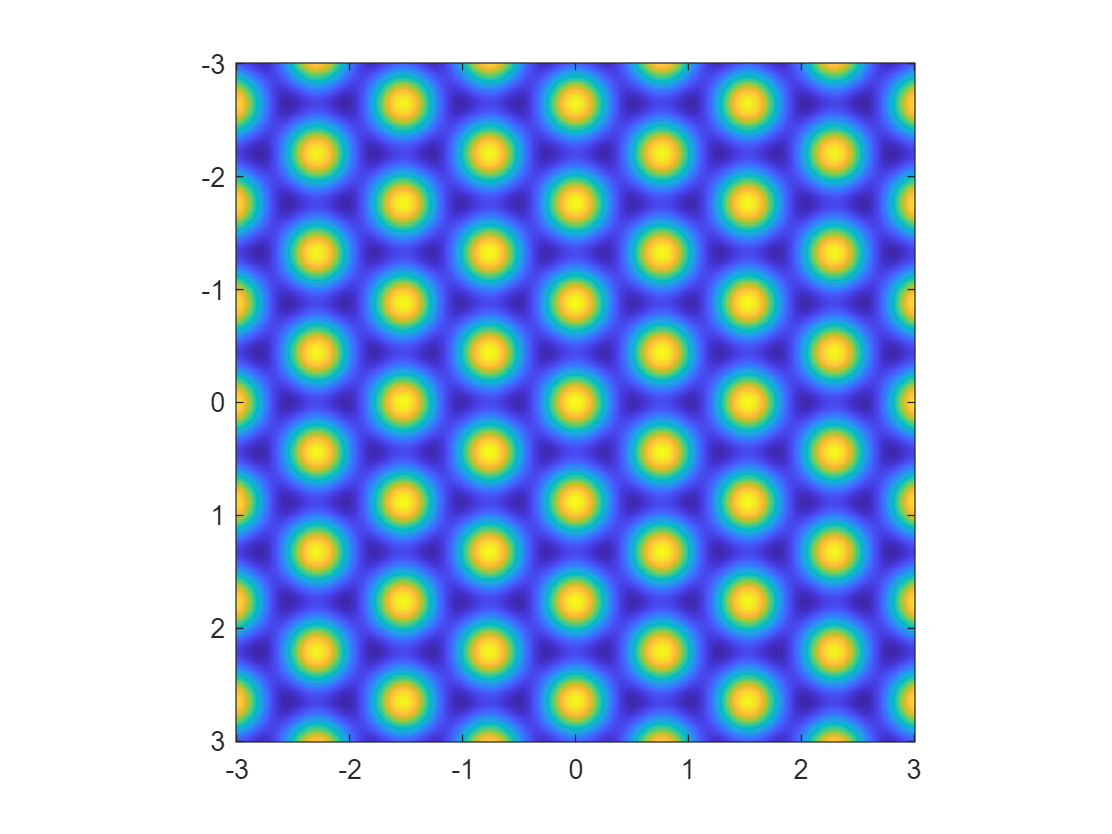

Beam.Power = [300;300;300];
Beam.Waist = [28,40;28,40;28,40];
Beam.Wave = 0.935;
Beam.Ang = [0,45;120,45;240,45];
Beam.Pol = [0,0;0,0;0,0];

XRange = -3:0.01:3;
YRange = -3:0.01:3;
% XRange = -100:100;
% YRange = -100:100;

[Y,X,Z] = meshgrid(YRange,XRange,0);
I = gaussianFull(Beam,[X(:),Y(:),Z(:)]);
imagesc(YRange,XRange,reshape(I,length(XRange),length(YRange)))
daspect([1 1 1])